cd('C:\Users\PC\Desktop\3081\Content-based-Image-Retrieval')

%CIFAR100
% rootFolder = 'cifar-100-matlab\CIFAR-100\TEST';
% categories = {'cup','dinosaur','forest','hamster'};

%COREL80
rootFolder = 'CorelDB';
categories = {'art_antiques','obj_car','sc_sunset','wl_buttrfly','bld_sculpt'};

imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
imagesPerClass = 100;
[trainingSet, testingSet] = splitEachLabel(imds, imagesPerClass, 'randomize'); 

featureSet = [];
ref = [];
numImages = numel(trainingSet.Files);

% preprocess the images in the dataset and collect:
% - their SIFT features into the featureSet matrix
% - their original image ID into the ref vector
for i = 1 : numImages
    I = im2gray(readimage(trainingSet,i));
%     I = imresize(I, [256 256]); % can try without this
    sift = detectSIFTFeatures(I).selectStrongest(25);
    [features, sift_points] = extractFeatures(I, sift);
    featureSet = cat(2, featureSet, features.');
    ref = cat(2, ref, repmat([i], 1, size(features,1)));
end


% construct LSH hash tables for featureSet
cd('vLSH')

% Tune hyperparameters
% Q = 144;  % # of queries
K = 32;   % # of nearest neighbors to search for each query
L = 10;   % # of tables
M = 25;   % # of dimensions at projection space
W = 1000; % bucket width
T = 10;   % # of additional probing bins

% Construct index tables
lshStruct = lshConstruct(featureSet, L, M, W);

Creating table 1/10
	Projecting data...
	13403 buckets
	min / max size: 1 / 11
	mean / median: 1.083340e+00 / 1
Creating table 2/10
	Projecting data...
	13762 buckets
	min / max size: 1 / 9
	mean / median: 1.055079e+00 / 1
Creating table 3/10
	Projecting data...
	13738 buckets
	min / max size: 1 / 28
	mean / median: 1.056922e+00 / 1
Creating table 4/10
	Projecting data...
	13797 buckets
	min / max size: 1 / 12
	mean / median: 1.052403e+00 / 1
Creating table 5/10
	Projecting data...
	13326 buckets
	min / max size: 1 / 24
	mean / median: 1.089599e+00 / 1
Creating table 6/10
	Projecting data...
	13558 buckets
	min / max size: 1 / 16
	mean / median: 1.070954e+00 / 1
Creating table 7/10
	Projecting data...
	13882 buckets
	min / max size: 1 / 12
	mean / median: 1.045959e+00 / 1
Creating table 8/10
	Projecting data...
	13604 buckets
	min / max size: 1 / 16
	mean / median: 1.067333e+00 / 1
Creating table 9/10
	Projecting data...
	13567 buckets
	min / max size: 1 / 11
	mean / median: 1.070244e+

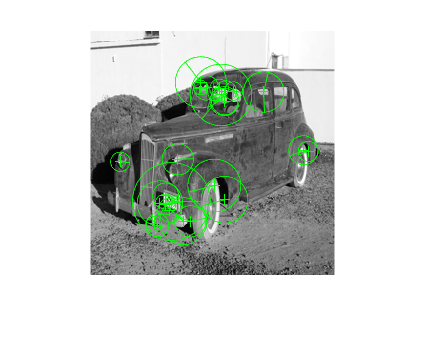

% query an input image
I = im2gray(imread("car1.jpg"));
I = imresize(I, [256 256]);
figure, imshow(I); hold on;
sift = detectSIFTFeatures(I).selectStrongest(25);
[queryFeatures, valid_points] = extractFeatures(I, sift);
plot(valid_points,'showOrientation',true);


[idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(queryFeatures.', featureSet, lshStruct, K, T);

Retrieving candidates from table 1
	-----> 0.068518 seconds
Retrieving candidates from table 2
	-----> 0.063033 seconds
Retrieving candidates from table 3
	-----> 0.063489 seconds
Retrieving candidates from table 4
	-----> 0.063286 seconds
Retrieving candidates from table 5
	-----> 0.070269 seconds
Retrieving candidates from table 6
	-----> 0.067537 seconds
Retrieving candidates from table 7
	-----> 0.067067 seconds
Retrieving candidates from table 8
	-----> 0.066889 seconds
Retrieving candidates from table 9
	-----> 0.072574 seconds
Retrieving candidates from table 10
	-----> 0.059745 seconds
Removing duplicate candidates...
	-----> 0.001091 seconds
Performing knn search...
	-----> 0.001332 seconds
Calculating candidate sizes...
	-----> 0.010509 seconds


% convert the feature IDs into their original image IDs
oriImages = zeros(size(idsMULTIPROBE));
for i = 1 : size(idsMULTIPROBE, 1)
    for j = 1 : size(idsMULTIPROBE, 2)
        if idsMULTIPROBE(i, j)>0
          oriImages(i,j) = ref(:,idsMULTIPROBE(i, j));
        end
    end
end

% aggregate and weight the image features by their ranks 
uniqImageIds = unique(oriImages);
N = numel(uniqImageIds);
weights = zeros(N,1);
fib = zeros(1, K); fib(K-1) = 1;
for i = K-2:-1:1
   fib(i) = fib(i+1)+fib(i+2);
end

for k = 1 : N
    weights(k) = sum(sum(oriImages == uniqImageIds(k))); % unranked weighting of NNs
    % ranked weighting of NNs
    % weights(k) = sum((K + (0 : K - 1) * -1) * (oriImages == uniqImageIds(k)));  % linear
    % weights(k) = sum(flip(exp(1 : K)) * (oriImages == uniqImageIds(k))); % exponential
    % weights(k) = sum(fib * (oriImages == uniqImageIds(k))); % fibonacci
end

ranks = sortrows([weights uniqImageIds], 1, 'descend');


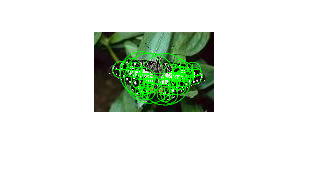

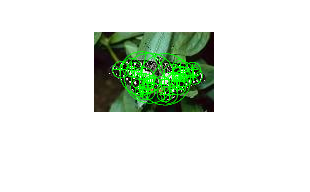

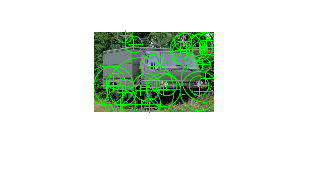

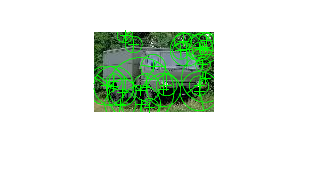

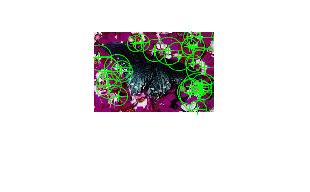

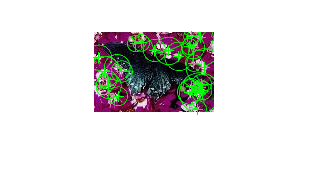

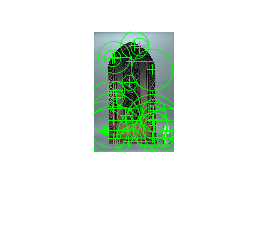

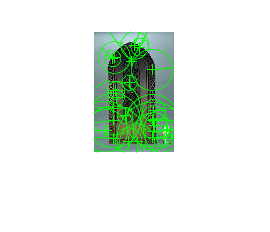

% display top 20 the matching images
for pic = 1 : min(10, length(ranks))
    if ranks(pic,2)>0
        % plot original image
        I = readimage(trainingSet, ranks(pic, 2));
        figure, imshow(I); hold on;
        sift = detectSIFTFeatures(im2gray(I)).selectStrongest(25);
        plot(sift,'showOrientation',true);

        % plot resized image
%         I = imresize(I, [256 256]);
        figure, imshow(I); hold on
        I = im2gray(I);
        sift = detectSIFTFeatures(I).selectStrongest(25);
        [queryFeatures, valid_points] = extractFeatures(I, sift);
        plot(valid_points,'showOrientation',true);
    end
end